clear all;
close all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');


london_outer_table=readtable('london_outer.csv');

london_inner_table=readtable('london_inner.csv');


ctrl_inputs_table= readtable('ctrl_inputs.csv');


xy_ref= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_ref= s_opt_table.x_S_opt;
steer_ref= ctrl_inputs_table.x_Delta;

u_steer= deg2rad([-15:0.5:15]);
dt= 0.0005;
state_init= [xy_ref(1, 1), xy_ref(1,2) , 0, 0];
run_length= 940;

dsteer= dt*deg2rad(15/0.2);

u_hist= [];
states_hist=[];
num_iter_hist=[];
v_last= 0;
steer_last= 0;


figure();

for i= 2:run_length
    ds= s_ref(i);
    state0= state_init;
    
    ref_devi= (xy_ref(i,2)- xy_ref(i-1,2))/(xy_ref(i,1)- xy_ref(i-1,1));
    dist_err_list=[];
    cord_err_list=[];
    devi_err_list=[];
    
    % generate path for each steer angle
    for j= 1:length(u_steer)
        
        [states_predict, u_predict]= PathPredict(state_init, dt, u_steer(j), dsteer, v_last, steer_last);
        states_predict= [state_init; states_predict];
        
        path_devi= (states_predict(end, 2)- state0(2))/((states_predict(end,1)- state0(1)));
        devi_err= abs(path_devi- ref_devi);
        devi_err_list= [devi_err_list; devi_err];
        

%         dist_err= (path_states(:,1)- xy_ref(i, 1)).^2+ (path_states(:,2)- xy_ref(i, 2)).^2;
%         dist_err_sum= sum(dist_err);
%         dist_err_list= [dist_err_list; dist_err_sum];
        
%         cord_err= abs(path_states(end,1)- xy_ref(i,1))+ abs(path_states(end,2)- xy_ref(i,2));
%         cord_err_list= [cord_err_list; cord_err];
        
%         plot(path_states(:,1), path_states(:,2));
%         hold on;
%         grid on; grid minor;
    end
    
    steer_id= find(devi_err_list== min(devi_err_list));
    [states_execute, u_execute, num_iter]= PathExecute(state0, dt, u_steer(steer_id), dsteer, v_last, steer_last, ds);
    
    u_hist= [u_hist; u_execute];
    states_hist= [states_hist; states_execute];
    num_iter_hist= [num_iter_hist; num_iter];
    
    state_init= states_execute(end,:);
    v_last= states_execute(end-1, 4);
    steer_last= u_execute(end,3);
end


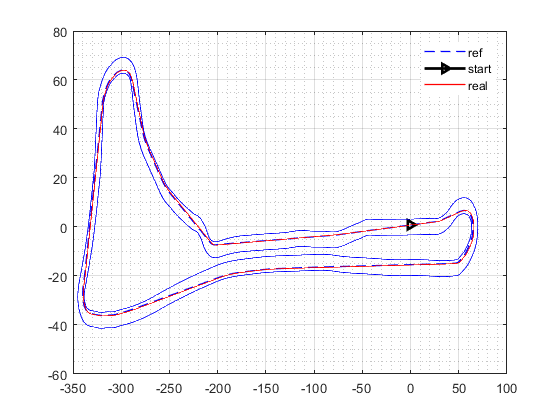

% plot path outline
plot_num= 1:run_length;
close;

figure();
plot(xy_ref(1,1), xy_ref(1,2), "Color", 'black', 'linewidth', 2.0, "LineStyle","-", "Marker",">");
hold on;
plot(xy_ref(plot_num, 1), xy_ref(plot_num, 2), 'linewidth', 1.0, "Color", 'blue', "LineStyle","--");
hold on;
plot(states_hist(:,1), states_hist(:,2), 'linewidth', 1.0, "Color", 'red');
hold on;
plot(london_outer_table.x_X, london_outer_table.y, 'blue', 'LineWidth', 1.0)
hold on;
plot(london_inner_table.x_X, london_inner_table.y, 'blue','LineWidth', 1.0)
hold off
grid on; grid minor;
legend('start', 'ref', 'real');

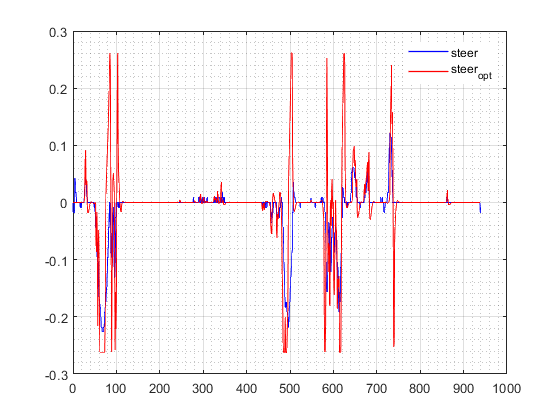


% plot steer input
plot_num= 0: run_length/length(u_hist):run_length;
close;
figure();

plot(plot_num(1:end-1), u_hist(:,3), 'blue', 'LineWidth', 1.0);
hold on;
plot(steer_ref,'red', 'LineWidth', 1.0);
hold off;
grid on; grid minor;
legend('steer', 'steer_{opt}');

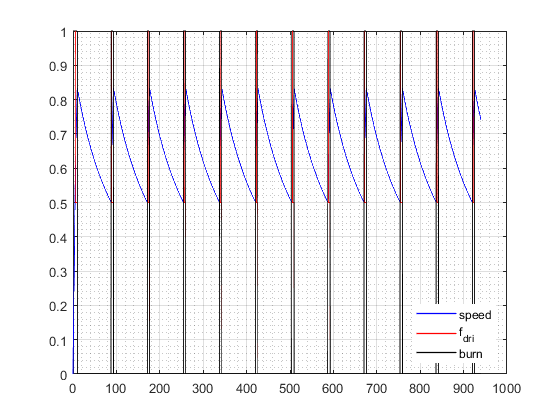

% plot engine input
close;
figure();
plot(plot_num(1:end-1) ,states_hist(:,4)/(30/3.6), 'linewidth', 1.0, "Color", 'blue');
hold on;
plot(plot_num(1:end-1) , u_hist(:,1), 'linewidth', 1.0, "Color", 'red');
hold on;
plot(plot_num(1:end-1) ,u_hist(:,2), 'linewidth', 1.0, "Color", 'black');
hold off;
legend('speed', 'f_{dri}', 'burn', "Location", "southeast");
grid on; grid minor;